# Segmentació per Entropía

openExample('images/TextureSegmentationExample')

## Netejar l'entorn

clc
close all
clear variables

## Llegim la imatge original

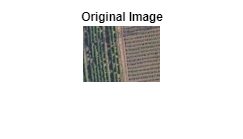

J = imread(['DemoPratFullAltMicro.png']);

figure
imshow(J), title('Original Image');

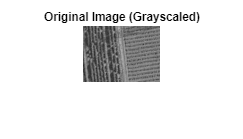


I = rgb2gray(J);

figure
imshow(I), title('Original Image (Grayscaled)');

## Creem una imatge de textura

E = entropyfilt(I);
S = stdfilt(I, ones(9));
R = rangefilt(I, ones(9));

## Reescalen E i S entre 0 - 1

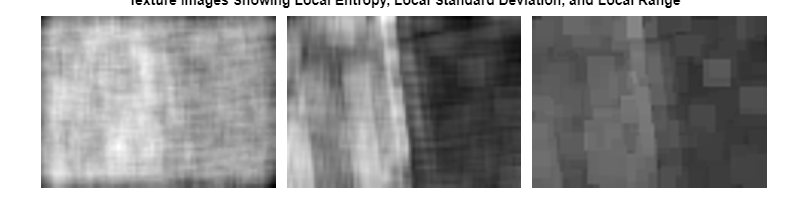

Eim = rescale(E);
Sim = rescale(S);

figure
montage({Eim, Sim, R}, Size = [1 3], BackgroundColor = 'w', BorderSize = 20),
title('Texture Images Showing Local Entropy, Local Standard Deviation, and Local Range');

## Crear una máscara para la textura inferior

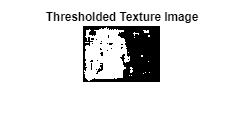

BW1 = imbinarize(Eim, 0.7);

figure
imshow(BW1), title('Thresholded Texture Image');

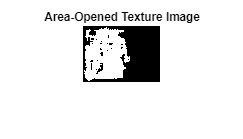


BWao = bwareaopen(BW1, 100);

figure
imshow(BWao), title('Area-Opened Texture Image');

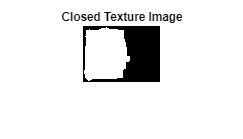


nhood = ones(9);
closeBWao = imclose(BWao, nhood);

figure
imshow(closeBWao), title('Closed Texture Image');

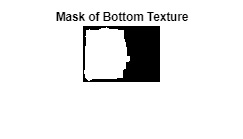


mask = imfill(closeBWao, 'holes');

figure
imshow(mask), title('Mask of Bottom Texture');

## Utilizar una máscara para segmentar texturas

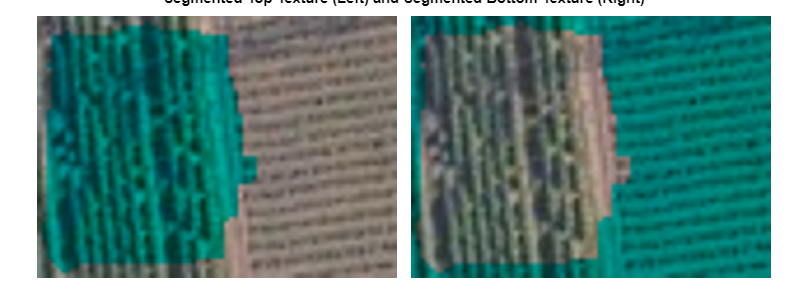

textureTop = J;
textureTop(mask) = 0;
textureBottom = J;
textureBottom(~mask) = 0;

figure
montage({textureTop,textureBottom}, Size = [1 2], BackgroundColor = 'w', BorderSize = 20),
title('Segmented Top Texture (Left) and Segmented Bottom Texture (Right)');

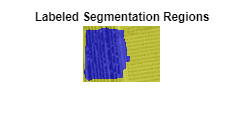


L = mask + 1;

figure
imshow(labeloverlay(I, L)), title('Labeled Segmentation Regions');

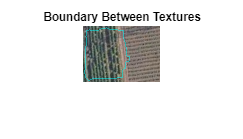


boundary = bwperim(mask);

figure
imshow(labeloverlay(J, boundary, Colormap = [0 1 1])), title('Boundary Between Textures');